# Worksheet 5, Part 3 / 4: Branching Processes and COVID-19

*Author: *Zachary del Rosario, Fall 2022

*Important Note:* Worksheet 5 comes to you in **four**** parts**; `worksheet5_part1_assignment.mlx`, `worksheet5_part2_assignment.mlx`, and `worksheet5_part3_assignment.mlx`, and `worksheet5_part4_assignment.mlx`

*Learning Objectives:* As a result of working through this notebook, you will learn:

- How to read a scientific paper (continued!); namely, how to *reproduce* results from a paper

- An example of a model that embraces randomness: the *branching process* model

- How comparing distributions in a model can help compare different assumptions about disease transmission

- How to pay *close attention* to details in a figure to *thoroughly *analyze simulation results

### Additional Files

Make sure to download these additional files from Canvas and place them in the same folder as this worksheet:

- `simulate_branching.m`

clear;

## Guided Reading of Althouse et al. (2020), Continued

We are going to continue reading the paper in the first part of this LiveScript.

Use the following exercise questions to guide your reading. Once you've finished all the reading questions (Exercises 1 and 2), the remaining questions will be self-contained within this part of the worksheet. Note that you can find the answers to many of the reading questions by studying Figure 2 in the paper.

### Exercise 1 / 9 (Reading)

Answer the following questions. Note that all of the terms below are *mentioned* in the Althouse et al. (2020) paper, but you will not find definitions in the paper. You will have to consult another resource. To keep things focused, we will give you the mathematical form of the branching process model (following [this Wikipedia article](https://en.wikipedia.org/wiki/Branching_process))


$$Z_{n+1} = \sum_{i=1}^{Z_n} X_{n, i}$$$


- In your own words, what is a *branching process*?

-  *(Write your response here) *It is used to describe the change in a population over a certain amount of time. When describing reproduction, the number of offspring for each parent is determined by a probability distribution.

- What physical quantity do Althouse et al. use a branching process to model? What previous model have we seen that is similar to this model?

-  *(Write your response here) *They use a branching process to model the number of infections spreading from one individual to another.

- What role does $n$ play in the author's model?

-  *(Write your response here) *It represents the number of timesteps.

- Which term in the branching process model relates to the two distributions—poisson and negative binomial—we discussed last time?

-  *(Write your response here) *The distribution of the number of secondary infections per infected individual.

- Does this form of the branching process model *explicitly* include the number of *susceptible* people in a population?

-  *(Write your response here) *No

Now that we've learned a little bit about the model that the authors are using, let's study some of the results they present from their modeling work.

### Exercise 2 / 9 (Reading)

Take a look at Figure 2 of Althouse et al. (2020). Using the results shown in the figure and details from its caption, answer the questions below.

- What is the initial number of infected persons in each simulation? What is the initial number of susceptible persons? What is the assumed $R_0$ value? What is the dispersion parameter $k$ for the negative binomial model?

-  *Initial infected: *1

- *    Initial susceptible: *9/99/999/999,999

- *    Assumed *$R_0$: 2.626

- *    Dispersion parameter *$k$: 0.1625

- Take a look at the **Infections** panels; what do the black curves represent? What do the blue curves represent? What do the purple curves represent? What does the red dashed line represent?

-  *Black curves: *The actual number of infections observed in the simulation.

-  *Blue curves: *The estimated number of infections based on a Poisson distribution.

-  *Purple curves: *The estimated number of infections based on a negative binomial distribution.

- *    Red dashed line: *The level of infections at which an event can be defined as a superspreading event.

- The "theoretical values" curve is what we would predict if we assumed that every primary infection led to *exactly* the mean number of secondary cases. What are the limitations of this assumption? Are the limitations of the "theoretical" curve more severe for the negative binomial model or poisson model?

-  *(Write your response here) *Some limitations include variability in transmission and SSEs, which lead to overdispersion in the distribution of secondary infections. The limitations are more severe for the Poisson model since it lacks the dispersion parameter of the binomial model, which can better account for SSEs.

- Which curves tend to agree with the "theoretical values" curve? Under what circumstances?

-  *(Write your response here) *The blue curve because it assumes no dispersion.

- Clearly, the simulated results are different based on the size of the population (e.g., Households are assumed to have 10 people, while Cities are assumed to have 1,000,000). Can the simple branching process model we discussed above replicate this changing behavior? Why or why not?

-  *(Write your response here) *No, because the simple branching process model does not take into account the specific characteristics and dynamics of different population sizes or settings.

Now that we've made sense of the results from Figure 2, let's try to reproduce the results by re-creating the model!

## Implementing a Branching Process

To implement the branching process model, we need to draw realizations of $X_{t, i}$. The $X_{t, i}$ represent the number of secondary cases resulting at timestep $t$ from infected individual $i$. To implement the model, we need to define a distribution for the $X_{t, i}$.

### Exercise 3 / 9

Implement the secondary case distributions for independent infections and super-spreading events (SSEs) using the same choices made in Althouse et al. (2020).

*Hint*: In the previous part of the worksheet (Part 2, Exercise 7) you worked out how to correctly *parameterize* distributions in Matlab.

% TODO: Implement distributions for independent infections and
% super-spreading events (SSEs) that match the modeling choices in Althouse
% et al. (2020)
R0 = 2.6;
k = 0.16;
r = k;
p = r/(R0+r);
pd_indep = makedist('Poisson', 'lambda', R0); % Poisson distribution
pd_sse = makedist('NegativeBinomial', 'r', r, 'p', p);   % Negative Binomial distribution

% NOTE: Do not edit this code; use this to check your work
assert(strcmp(pd_indep.DistributionName, 'Poisson'), 'Your independent infection distribution is not poisson')
assert(abs(mean(pd_indep) - 2.6) < 1e-3, 'The mean of your independent infection distribution is incorrect')
assert(strcmp(pd_sse.DistributionName, 'Negative Binomial'), 'Your SSE distribution is not negative binomial')
assert(abs(mean(pd_sse) - 2.6) < 1e-3, 'The mean of your SSE distribution is incorrect')
assert(abs(var(pd_sse) - 44.85) < 1e-3, 'The variance of your SSE distribution is incorrect')
disp('Assertions passed')

Assertions passed


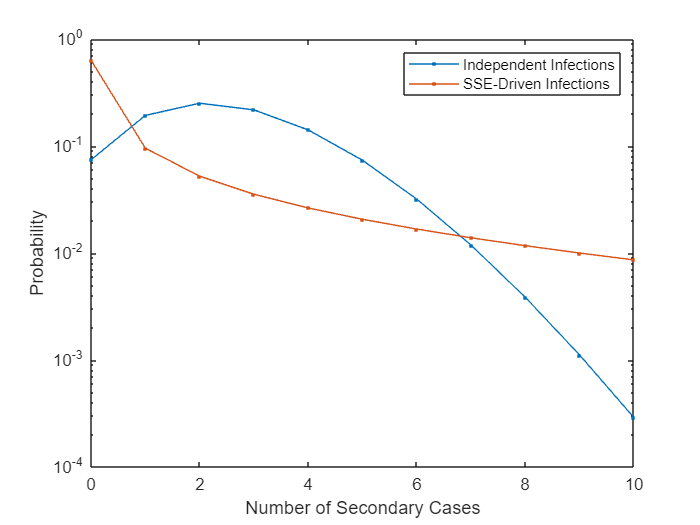


% Visualize
x = 0:10;
y_indep = pdf(pd_indep, x);
y_sse = pdf(pd_sse, x);

figure();
semilogy(x, y_indep, '.-', 'DisplayName', 'Independent Infections'); hold on;
semilogy(x, y_sse, '.-', 'DisplayName', 'SSE-Driven Infections')
xlabel('Number of Secondary Cases')
ylabel('Probability')
legend()

Next, we need to be able to draw realizations from these distributions.

### Exercise 4 / 9

Draw a random sample of values from the distributions you defined above. Provide the realization as a *column vector*. Answer the questions below.

*Hint*: We learned how to draw realizations in the previous part of the worksheet (Part 2, Exercise 8).

% NOTE: Do not modify this code; use this current state to simulate the
% action of the model
I = 3; % Current number of infected persons

% TODO: Draw random realizations from your distributions to model. Make
% sure your sample is in the form of a *column vector*.
X_indep = random(pd_indep, 1, I);
X_sse = random(pd_sse, 1, I);
X_indep = X_indep';
X_sse = X_sse';
% NOTE: Do not modify this code; use this to check your results
assert(length(X_indep) == I, 'Wrong number of realizations for X_indep')
assert(numel(X_indep) == I, 'Wrong number of realizations for X_indep; make sure not to generate a matrix!')
assert(size(X_indep, 1) == I, 'X_indep is not a column vector')
assert(length(X_sse) == I, 'Wrong number of realizations for X_sse')
assert(numel(X_sse) == I, 'Wrong number of realizations for X_sse; make sure not to generate a matrix!')
assert(size(X_sse, 1) == I, 'X_sse is not a column vector')
disp('Assertions passed')

Assertions passed



sum(X_indep)

ans = 12

sum(X_sse)

ans = 0

- What does `X_indep` represent? What does `sum(X_indep)` represent?

-  `X_indep` *represents: (Write your response here) *It represents the random values that make up the independent realization.

-  `sum(X_indep)` *represents: (Write your response here) *The total number of infected people for a realization.

- What is the average number of secondary cases expected from this initial number of infected persons? Will you *ever* see *exactly* this number from a realization? Why or why not?

-  *(Write your response here) *5 cases, there is a possibility that this exact number could be seen, even if it is low.

- How many total secondary cases did you see from the two models?

-  *Independent infections: (Write your response here) *14

-  *Super-spreading events: (Write your response here) *0

### Action: Advancing the simulation

A subtle point about the branching process model is that it assumes that infected individuals are infected for *exactly *one timestep. This means the number of infected at every stage is *exactly equal* to the new number of infected persons


$$I_{t+1} = 0 + \Delta I_{t+1}$$


With this clarified, we can now implement the *simple *version of the branching process model. The full model is given by


$$I_{t+1} = \Delta I_{t+1} \\
\Delta I_{t+1} = \sum_{i=1}^{I_t} X_{t, i}
$$


with $X_{t,i}$ representing the number of secondary cases per individual, and an initial number of infected $I_0$.

*Note:* You might be wondering why $X_{t, i}$ has an index for the timestep $t$ *and* individual $i$, as opposed to just the individual $X_i$. This is because the number of secondary cases is generally *different for each timestep* $t$. This is a subtle point that will make more sense once you implement the model (in the next Exercise!).

### Exercise 5 / 9

Complete the code below to implement the simple branching process model. Answer the questions below.

*Hint:* Re-use the code you wrote for Exercise 4 within the `for` loop.

% NOTE: Do not edit this code
I0 = 1; % Initial number of infected persons
T = 7;  % Number of timesteps to simulate

I_indep = zeros(T, 1); I_indep(1) = I0;
I_sse = zeros(T, 1);   I_sse(1) = I0;

% TODO: Modify the code below to implement the action of the model
for i = 2:T
    delta_I_indep = random(pd_indep, 1, T);
    I_indep(i) = delta_I_indep(i);
    delta_I_sse = random(pd_sse, 1, T);
    I_sse(i) = delta_I_sse(i);
end

% NOTE: Do not edit this code; use this to check your work
assert(~all(I_indep(2:end) == I_indep(2) & (I_indep(2) ~= 0)), 'All values of I_indep are equal! Did you forget to draw a new realization every timestep?')
assert(~all(I_sse(2:end) == I_sse(2) & (I_sse(2) ~= 0)), 'All values of I_sse are equal! Did you forget to draw a new realization every timestep?')
disp('Assertions passed')

Assertions passed


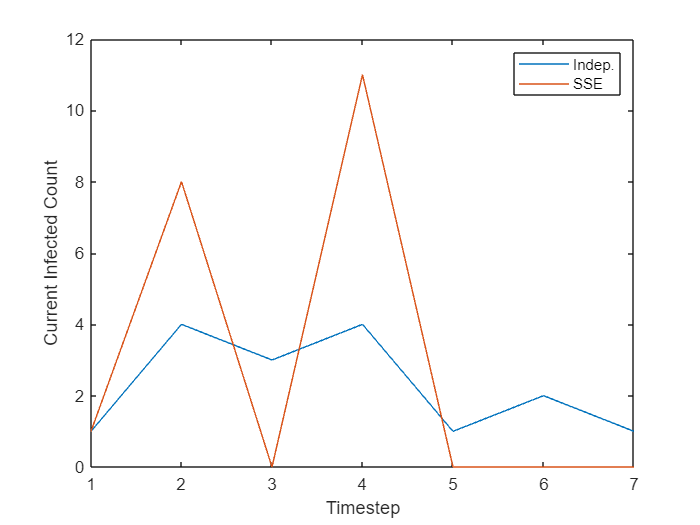


figure();
plot(1:T, I_indep, 'DisplayName', "Indep."); hold on;
plot(1:T, I_sse, 'DisplayName', "SSE")
xlabel('Timestep')
ylabel('Current Infected Count')
legend()

- What variables are tracked in the state? Is the number of susceptible individuals tracked in this form of the model?

-  *(Write your response here) *No, only who is infected

- Run your model a few times. What do you notice about the model that assumes independent infections? How about the model driven by super-spreading events (SSEs)? Which model tends to "take off" more frequently?

-  *(Write your response here) *Instead of a curve, there are sharp spikes. The independent model has larger and more frequent spikes when it does spike.

### Action: Representing the population size

To represent the population size, we will need to modify the model to track the number of susceptible individuals $S_t$. Tracking $S_t$ will allow us to *limit* the number of new infected persons $\Delta I_{t+1}$, which should not be able to exceed the current number of susceptible individuals $S_t$. (This is the same lesson we learned with the compartmental SIR model!) If we incorporate this lesson in the branching process model, we get this system of equations,


$$I_{t+1} =0+\Delta I_{t+1} \\
S_{t+1} =S_t-\Delta I_{t+1} \\
\Delta I_{t+1} = \min\left(\sum_{i=1}^{I_t} X_{t, i},\,\, S_t\right)
$$


You'll implement this form of the model next.

### Exercise 6 / 9

Implement the form of the branching process model that tracks the number of susceptible persons. Answer the questions below.

% NOTE: Do not edit this code
I0 = 1;      % Initial number of infected persons
n_pop = 100; % Total population size
T = 7;       % Number of timesteps to simulate
% Track the state for both
I_indep = zeros(T, 1); I_indep(1) = I0;
I_sse = zeros(T, 1);   I_sse(1) = I0;

% TODO: Modify the code below to set the initial state for the susceptibles
% for both models
S_indep = zeros(T, 1);
S_sse = zeros(T, 1);

% TODO: Modify the code below to implement the action of the model
for i = 2:T
    delta_I_indep = random(pd_indep, 1, T);
    I_indep(i) = delta_I_indep(i);
    S_indep(i) = n_pop - delta_I_indep(i);
    delta_I_sse = random(pd_sse, 1, T);
    I_sse(i) = delta_I_sse(i);
    S_sse(i) = n_pop - delta_I_sse(i);
end

% NOTE: Do not edit this code; use this to check your work
assert(~all(I_indep(2:end) == I_indep(2) & (I_indep(2) ~= 0)), 'All values of I_indep are equal! Did you forget to draw a new realization every timestep?')
assert(all(I_indep <= n_pop), 'I_indep exceeds the total population!')
assert(~all(I_sse(2:end) == I_sse(2) & (I_sse(2) ~= 0)), 'All values of I_sse are equal!  Did you forget to draw a new realization every timestep?')
assert(all(I_sse <= n_pop), 'I_sse exceeds the total population!')
disp('Assertions passed')

Assertions passed


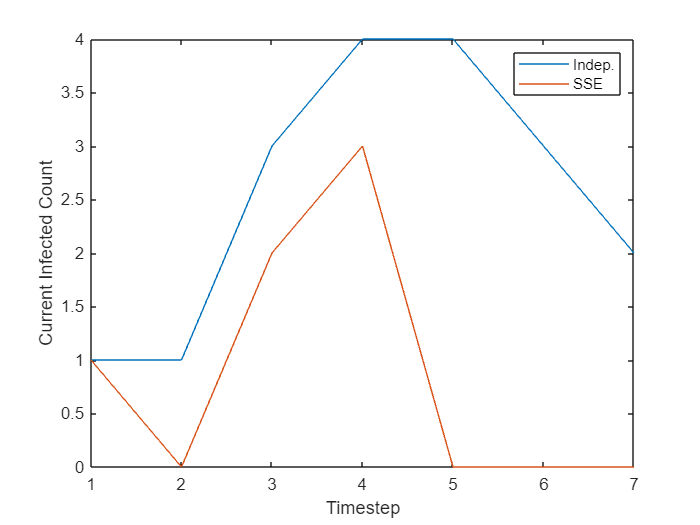


figure();
plot(1:T, I_indep, 'DisplayName', "Indep."); hold on;
plot(1:T, I_sse, 'DisplayName', "SSE")
xlabel('Timestep')
ylabel('Current Infected Count')
legend()

- Does the form of the model allow the number of infected persons to exceed the total population? Why?

-  *(Write your response here) *No, because the way the random numbers are set up they cannot exceed the total population, also people are only infected for one timestep.

- Does this form of the model track the number of recovered individuals? Do we *need* to track the recovered individuals in order to determine the number of infected persons?

-  *(Write your response here) *No

Now that we've built the model, we can reproduce the results from Figure 2!

## Reproducing Figure 2

I've encapsulated all of the code for the branching process model (with susceptible individuals) in the script `simulate_branching.m`. Now that we have a fully-implemented model, we can use it to do useful work. As we learned back in Worksheet 4, it is not meaningful to run a *single* realization of a random model. Instead, we must run multiple realizations and compute statistics.

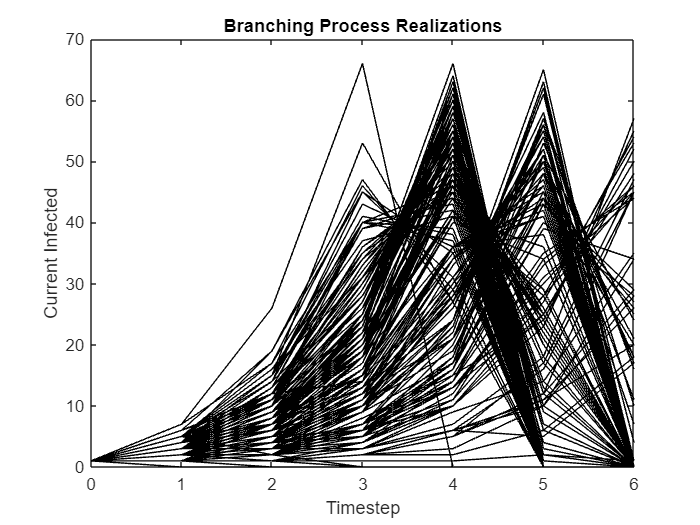

% Set common parameters
I0 = 1;
T = 7;
n_pop = 100;
n_realizations = 200;

% Run 10 realizations
rng(101);
I_all = zeros(T, n_realizations);
for i = 1:n_realizations
    I_all(:, i) = simulate_branching(I0, pd_indep, n_pop, T);
end

% Visualize all runs
T_gen = 0:(T - 1); % NOTE: This is to help match the way Althouse et al. report "time"
figure();
plot(T_gen, I_all, 'k')
xlabel('Timestep')
ylabel('Current Infected')
title('Branching Process Realizations')

At first inspection, it might appear that all of the realizations result in an outbreak. However, you would be *wrong* to think that!

### Exercise 7 / 9

Find the indices of all realizations that "take off"; that is, cases where an outbreak occurs. Answer the questions below.

*Hint:* You will have to come up with a way to identify "take off" cases using MATLAB code.

% TODO: Find the indices of realizations in I_all that "take off";
% that is, cases where an outbreak occurs.
i_takeoff = zeros(1,200);
n = 1;
for t = 1:200
    if (I_all(2,t) > 0)
        i_takeoff(1,t) = 1;
    end
end

% NOTE: Do not edit this code
n_takeoff = sum(i_takeoff) % Number of cases that "take off"

n_takeoff = 184

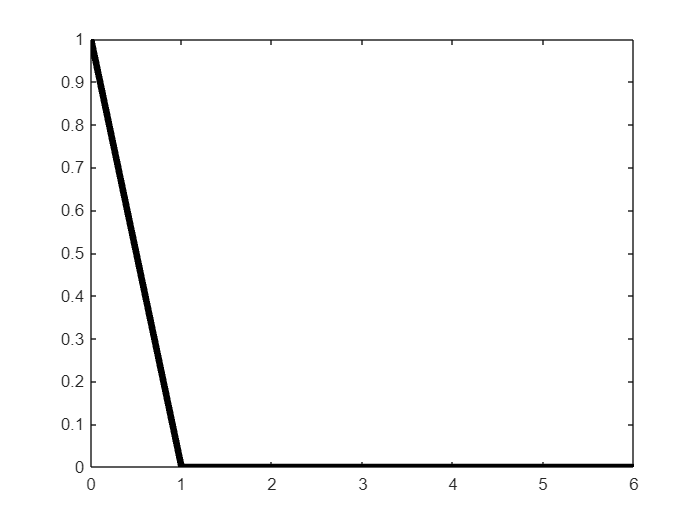


% Visualize highlighting the 'takeoff' cases
T_gen = 0:(T - 1); % NOTE: This is to help match the way Althouse et al. report "time"
figure();
plot(T_gen, I_all(:, ~i_takeoff), 'k', 'LineWidth', 4); hold on

plot(T_gen, I_all(:, i_takeoff), 'Color', [0.5 0.5 0.5])

Index in position 2 is invalid. Array indices must be positive integers or logical values.

ylim([-1, 70])
xlabel('Timestep')
ylabel('Current Infected')
title('"Take off" Realizations')

% NOTE: Do not edit this code; use this to check your work
assert(all(i_takeoff == (I_all(2, :) > 0)), 'You have the wrong indices')
disp('Assertions passed')

- How many realizations (out of 200 total) take off?

- *    (Write your resonse here) *184

- Althouse et al. choose to compute the mean over all realizations, as well as the mean over only those realizations that "take off." Why do you think they do this?

- *    (Write your resonse here) *To show that the mean is not a good indicator of reality as one extreme situation can drastically change the number.

## Metrics: What goes in the mean?

Until this point, we've talked about taking "the" mean of a dataset. However, there are many cases where we should think carefully about which observations go *in* the mean. Selecting relevant cases for aggregation is an important part of designing a metric relevant to our modeling question.

To illustrate: Let's look at a simple dataset of the measured heights for six individuals.

tab_heights = table();
tab_heights.height = [175; 161; 174; 160; 177; 162]; % Height (cm)
tab_heights.gender = ['M'; 'F'; 'M'; 'F'; 'M'; 'F'];

tab_heights

tab_heights = 6×2 table
    height    gender
    ______    ______

     175        M   
     161        F   
     174        M   
     160        F   
     177        M   
     162        F   


To summarize this dataset, we can compute the mean height including all persons:

% Compute the mean height over all persons
mean(tab_heights.height)

ans = 168.1667

However, it is an empirical fact that [men tend to be taller than women](https://en.wikipedia.org/wiki/Average_human_height_by_country). This suggests that we ought to compute a mean for both populations separately:

% Compute the mean height for men and women separately
mean(tab_heights.height(tab_heights.gender == 'M'))

ans = 175.3333

mean(tab_heights.height(tab_heights.gender == 'F'))

ans = 161

Here we can see that the heights of men and women tend to be different.

This is one way using "a single value" tends to fail us. In cases where we aggregate distinct groups, we neglect any differences between those groups. In cases where we can identify distinct groups, cases, or populations, we are better off reporting summaries for each group.

Althouse et al. apply a similar style of reasoning in their analysis. There are at least two distinct cases for realizations from their model:

- Realizations where the infection immediately dies out

- Realizations where the infection "takes off"

Taking the mean over all realizations includes those cases where no infection outbreak occurred. Taking the mean over takeoff cases only leads to a more targeted accounting for the severity of disease outbreaks. The two quantities measure different things, so the authors chose to report *both *quantities.

You'll practice computing the mean over specific realizations in the next exercise.

### Exercise 8 / 9

Compute the mean infection trajectory over only the realizations that take off. Answer the questions below.

*Hint 1:* You can (and should!) re-use the `i_takeoff` you computed above.

*Hint 2:* You will have to read the documentation for `mean()` so you can take the mean along the correct matrix dimension `dim`.

% TODO: Take the mean of I_all over only those realizations that "take off"
I_takeoff_mean = zeros(1,n_takeoff);
n = 1;
for t = 1:200
    if (i_takeoff(1,t) == 1)
        n = n+1;
        I_takeoff_mean(1,n) = mean(I_all(:,t));
    end
end

% NOTE: Do not edit this code; use this to check your work
assert(all(size(I_takeoff_mean) == [7, 1]), 'Your I_takeoff_mean is the wrong size. Did you take the mean over the correct matrix dimension?')
disp('Assertions passed')

Assertions passed



% Visualize highlighting the 'takeoff' cases
T_gen = 0:(T - 1); % NOTE: This is to help match the way Althouse et al. report "time"
figure();
plot(T_gen, I_all(:, ~i_takeoff), 'k', 'LineWidth', 4); hold on

plot(T_gen, I_all(:, i_takeoff), 'Color', [0.5 0.5 0.5])

Index in position 2 is invalid. Array indices must be positive integers or logical values.

plot(T_gen, mean(I_all, 2), 'b', 'LineWidth', 2)
plot(T_gen, I_takeoff_mean, 'color', [0.79 0.58 0.95], 'LineWidth', 2)
ylim([-1, 70])
xlabel('Timestep')
ylabel('Current Infected')
title('"Take off" Realizations')

- What is the difference between the mean trajectory over takeoff cases only (purple line) and the mean over all cases (blue line)? Is this difference large or small?

- *    (Write your response here)*

- What kind of scenario could cause the difference between the takeoff mean and mean over all cases to be *large*?

- *    (Write your response here)*

Finally, we have all of the tools and understanding we need to replicate Figure 2 from Althouse et al. (2020).

### Exercise 9 / 9

Complete the code below to simulate both models `n_realizations = 1000` times. Answer the questions below.

*Hint:* Use `help simulate_branching` to access the documentation for the simulation function. Also, see the example code above for an example of its use.

*Note:* The following code is a bit compute-intensive. It may take a few moments (say, up to half a minute) for the code to run.

% NOTE: Do not edit this code
T = 7;       % Number of timesteps to simulate, matching Althouse et. al (2020)
I0 = 1;      % Number of initial infected, matching Althouse et. al (2020)
n_pop = 100; % Total size of population, similar to a small college....

% Smaller number of realizations than Althouse et al. (2020);
% chosen for speed
n_realizations = 1000; 
% Reserve space for simulation
I_all_indep = zeros(T, n_realizations);
I_all_sse = zeros(T, n_realizations);

% TODO: Write your own for loop to simulate the models `n_realizations` times and
% store the results using correct indexing.

% NOTE: Do not edit this code
% If your code is correct, the following should replicate the
% results from Althouse et al. (2020) Figure 2, population == 100 case
T_gen = 0:(T-1);
% Take conditional mean
idx_indep = (I_all_indep(2, :) > 0);
I_takeoff_indep = mean(I_all_indep(:, idx_indep), 2);
idx_sse = (I_all_sse(2, :) > 0);
I_takeoff_sse = mean(I_all_sse(:, idx_sse), 2);

figure(); subplot(2, 1, 1)
semilogy(T_gen, I_all_indep, "Color", [0.4, 0.4, 0.4, 0.2]); hold on;
semilogy(T_gen, mean(I_all_indep, 2), 'b', 'LineWidth', 2)
semilogy(T_gen, I_takeoff_indep, 'color', [0.79 0.58 0.95], 'LineWidth', 2)
semilogy(T_gen, R0 .^ T_gen, 'r--', 'LineWidth', 2) % mean line
ylim([0.5 n_pop])
title('Poisson Case')
ylabel('Current Infected')
xlabel('Timestep (Generation)')

subplot(2, 1, 2)
semilogy(T_gen, I_all_sse, "Color", [0.4, 0.4, 0.4, 0.2]); hold on;
semilogy(T_gen, mean(I_all_sse, 2), 'b', 'LineWidth', 2)
semilogy(T_gen, I_takeoff_sse, 'color', [0.79 0.58 0.95], 'LineWidth', 2)
semilogy(T_gen, R0 .^ T_gen, 'r--', 'LineWidth', 2) % mean line
ylim([0.5 n_pop])
title('Negative Binomial Case')
ylabel('Current Infected')
xlabel('Timestep (Generation)')

- Compare your results to Figure 2 from Althouse et al. (2020), specifically the panels corresponding to a population of `100`. Do your results look similar to theirs? (If not, you have not implemented the code above correctly... make sure to fix your code!)

-  *(Write your response here)*

- Compare the blue curves across the two models: These represent the mean behavior over *all* realizations. Which model tends to exhibit more infections, according to this metric? (Note that the dashed red line is identical across both panels.)

-  *(Write your response here)*

- Compare the purple curves across the two models: These represent the mean behavior over *only* those realizations that have a nonzero number of infected at Timestep 1 (those simulations that "take off"). Which models tends to exhibit more infections, according to this metric? (Note that the dashed red line is identical across both panels.)

-  *(Write your response here)*

- Does the poisson model have any realizations where over half the population is infected by Timestep 1? How about the negative binomial model? (Note that the vertical axis is a log-scale—the ticks represent multiples of $10^x$, for instance $1, 2, 3, 4, \dots$, followed by$10, 20, 30, 40, \dots$, and so on.)

-  *(Write your response here)*

- Remember that the negative binomial model represents a disease with super-spreading events (SSEs), while the poisson model represents a disease without SSEs. How do the two diseases compare?

-  *(Write your response here)*

## Looking Forward

The work you've done here should give you a solid understanding of the branching process model and what its simulation results look like. The comparisons above also help us understand how super-spreading events (SSEs) potentially change the outcome of a disease outbreak. In the next (and final) part of Worksheet 5, we'll take a closer look at uncertainty in models.